Create database!

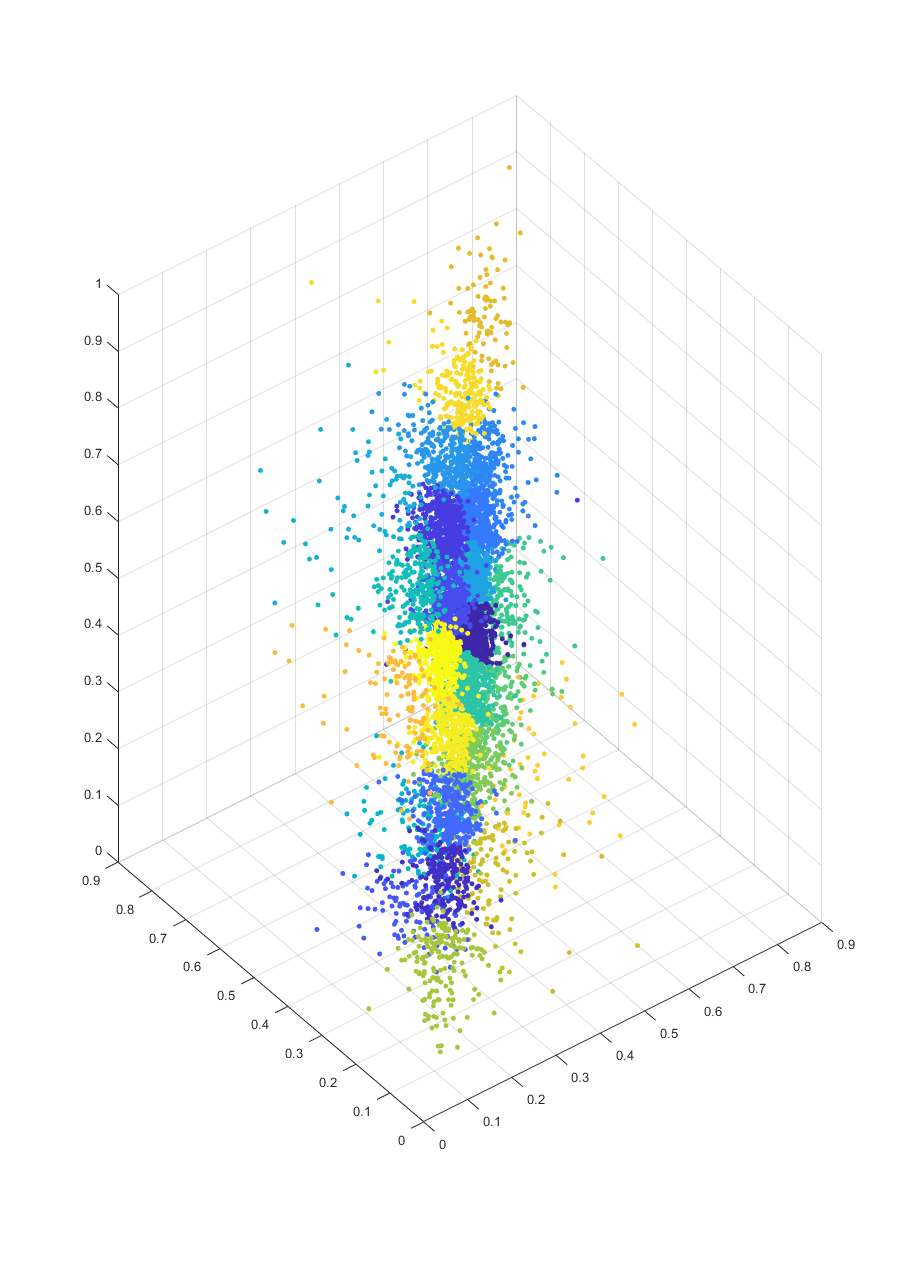

Database has been created containing:200 images


numberOfCluster = 25;
clusterSize = 8; 
tinyImgSize = 24; 

% The resulting number of images comes from numberOfCluster * cluterSize
% 25 * 4 = 100 images for example

[smallDatabase, meanSmallDB] = filtering(numberOfCluster,clusterSize,tinyImgSize);

Create reconstructed image from smaller images that comes from the database

% Name of the file (Must be of type jpg)
fileName = 'grill.jpg';
% The size for each "cell" that goes through the image. Recommended size = 8
cellSize = 8;
% Number of 'good-matches' to use SSIM on. Higher = better quality (but also more compute heavy)
n = 3;

% call function to create image
[imgOUT, imgSSIM, imgSNR, imgDE] = image_rec_v1(fileName, smallDatabase, meanSmallDB, cellSize, n);

Image dimensions are not divisible by:8
The size of the image has been changed to:1168x728
Some information from the original image has therefore been lost
Image is processing...10%
Image is processing...20%



% show the final image
imshow(lab2rgb(imgOUT))